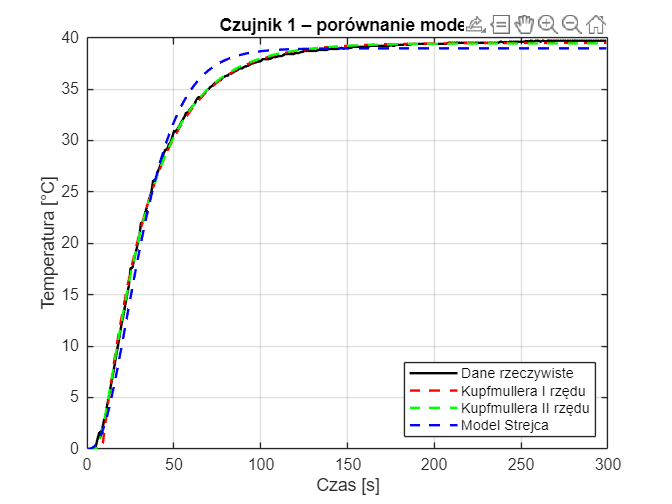

clear; clc; close all;
load piecyk_3_cels.mat

% Przygotowanie danych
czas = 0:1:299;
y = piecyk_3_cels(:, 1);
y = y - y(1);  % normalizacja
u = ones(length(czas), 1);
k_static = y(end);

% === Model Kupfmullera I rzędu ===
param1 = [39.4840, 28.4364, 8.6303];  % k, T, tau
model1 = tf(param1(1), [param1(2), 1], 'OutputDelay', param1(3));
ym1 = step(model1, czas);

% === Model Kupfmullera II rzędu ===
param2 = [39.4393, 27.3659, 4.7081, 4.6118];  % k, T1, T2, tau
model2 = tf(param2(1), [param2(2)*param2(3), param2(2)+param2(3), 1], 'OutputDelay', param2(4));
ym2 = step(model2, czas);

% === Model Strejca ===
n = 3;
param3 = [38.9525, 11.3311];  % k, T
bieguny = (-1/param3(2)) * ones(1, n);
model3 = zpk([], bieguny, param3(1) / param3(2)^n);
ym3 = step(model3, czas);

% === Rysowanie wykresów ===
figure;
plot(czas, y, 'k', 'LineWidth', 1.5); hold on;
plot(czas, ym1, 'r--', 'LineWidth', 1.5);
plot(czas, ym2, 'g--', 'LineWidth', 1.5);
plot(czas, ym3, 'b--', 'LineWidth', 1.5);
grid on;
xlabel('Czas [s]');
ylabel('Temperatura [°C]');
title('Czujnik 1 – porównanie modeli');
legend('Dane rzeczywiste', ...
       'Kupfmullera I rzędu', ...
       'Kupfmullera II rzędu', ...
       'Model Strejca', ...
       'Location', 'southeast');